addpath 'E:\MATLAB'
addpath 'E:'\MATLAB\Images\
%ImageNames={'baby.png';'bird.png';'woman.png';'monarch.png';'airplane.png';'arctichare.png';'peppers1.tiff';'peppers2.png';'foreman.png'};
%ImageNames={'kodim01.png';'kodim02.png';'kodim03.png';'kodim04.png';'kodim05.png';'kodim06.png';'kodim07.png';'kodim08.png';'kodim09.png';'kodim10.png';'kodim11.png';'kodim12.png';'kodim13.png';'kodim14.png';'kodim15.png'};
ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'aerial9.tiff';'aerial10.tiff'};
PSNR_R=zeros(size(ImageNames,1),1);
PSNR_G=zeros(size(ImageNames,1),1);
PSNR_B=zeros(size(ImageNames,1),1);
SSIM_R=zeros(size(ImageNames,1),1);
SSIM_G=zeros(size(ImageNames,1),1);
SSIM_B=zeros(size(ImageNames,1),1);
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=(imread(string));
    R = double(A(:,:,1)); % Red channel
    G = double(A(:,:,2)); % Green channel
    B = double(A(:,:,3)); % Blue channel
    SR31=imresize(R,2/3,'bicubic');
    SR3=imresize(SR31,3/2,'bicubic');
    SR32=imresize(G,2/3,'bicubic');
    SR3G=imresize(SR32,3/2,'bicubic');
    SR33=imresize(B,2/3,'bicubic');
    SR3B=imresize(SR33,3/2,'bicubic');
    [m,n]=size(SR3B);
    RR=imresize(R,[m n]);
    GG=imresize(G,[m n]);
    BB=imresize(B,[m n]);
    imageUpscaled=cat(3,uint8(SR3),uint8(SR3G),uint8(SR3B));
    imageOriginal=cat(3,uint8(RR),uint8(GG),uint8(BB));
    LRimage=cat(3,uint8(SR31),uint8(SR32),uint8(SR33));
    PSNR_R(i)=psnr(uint8(SR3),uint8(RR));
    PSNR_G(i)=psnr(uint8(SR3G),uint8(GG));
    PSNR_B(i)=psnr(uint8(SR3B),uint8(BB));
    SSIM_R(i)=ssim(uint8(SR3),uint8(RR));
    SSIM_G(i)=ssim(uint8(SR3G),uint8(GG));
    SSIM_B(i)=ssim(uint8(SR3B),uint8(BB));
end
toc

Elapsed time is 5.265240 seconds.


%imwrite(imageOriginal,'E:\MATLAB\IMAGE SETS\SR_testing_datasets\resultsfactor32\lena.png')
%imwrite(imageUpscaled,'E:\MATLAB\IMAGE SETS\SR_testing_datasets\resultsfactor32\lenabicubic.png')
%imwrite(LRimage,'E:\MATLAB\IMAGE SETS\SR_testing_datasets\resultsfactor32\lenaLR.png')

T=table(ImageNames,PSNR_R,PSNR_G,PSNR_B,SSIM_R,SSIM_G,SSIM_B)

T = 10×7 table
       ImageNames        PSNR_R    PSNR_G    PSNR_B    SSIM_R     SSIM_G     SSIM_B 
    _________________    ______    ______    ______    _______    _______    _______

    {'aerial1.tiff' }    32.544    35.992    41.566    0.84668    0.89652    0.94601
    {'aerial2.tiff' }    30.306    34.151      39.5    0.83298    0.86257     0.9201
    {'aerial3.tiff' }    26.247    28.377    35.883    0.79579    0.78953    0.87141
    {'aerial4.tiff' }    27.355    28.648    31.481    0.83283     0.8289    0.80526
    {'aerial5.tiff' }     33.92    34.926    36.714     0.8443    0.85111     0.8519
    {'aerial6.tiff' }    30.605    32.636    37.461    0.82868    0.83554     0.8806
    {'aerial7.tiff' }    28.174    32.117    40.012    0.82903    

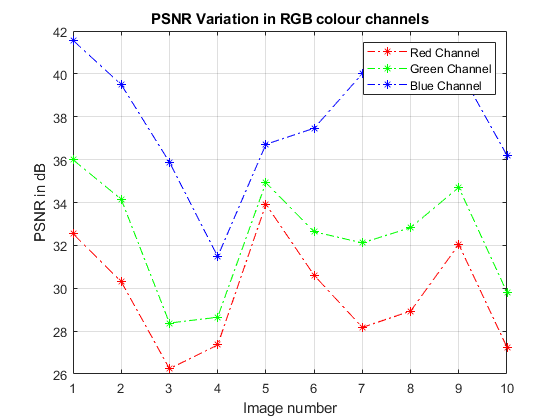

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\BICUBICFactorOf32.xlsx'];
writetable(T,path_format)
writetable(T,path_format)
n=1:size(ImageNames,1);
figure;
plot(n,PSNR_R,'-.r*',n,PSNR_G,'-.g*',n,PSNR_B,'-.b*')
grid on
ylabel ('PSNR in dB')
xlabel ('Image number')
title ('PSNR Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel')

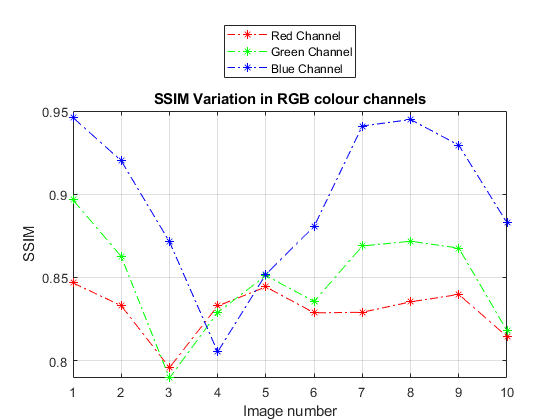

figure;
plot(n,SSIM_R,'-.r*',n,SSIM_G,'-.g*',n,SSIM_B,'-.b*')
grid on
ylabel ('SSIM')
xlabel ('Image number')
title ('SSIM Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel', ...
    'Location','northoutside')